%Load Pre-Trained AlexNet
clc
clear
net = alexnet;
layers = net.Layers;

%Read Dataset and Knowing Categories
path = fullfile(pwd);
filepath = [path,filesep,'Gender Classification'];
imds = imageDatastore(filepath,...  
    'IncludeSubfolders',true,...
    'LabelSource','foldernames'); 
label_class = unique(imds.Labels)

label_class = 2×1 categorical array
     Female 
     Male 


Categories = length(label_class);

% A=imds.Files(1);
% B=imread(A{1,1})
% C=imresize(B,[227 227]);
% imshow(C)

% We look at the first layer to see the size requirement
sizeRequirement = net.Layers(1).InputSize;
inputSize = sizeRequirement(1:2)

inputSize =    227   227



% % Create anonymous function
imds.ReadFcn = @(img) imresize(imread(img),inputSize);

%Splitting Train, Test, and Validation Dataset
[trainDS, valDS, testDS] = splitEachLabel(imds,0.7,0.15,0.15,'randomized');

layers

layers =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Convolution                   256 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
    

%Modifying pretrained model
numClasses = numel(unique(imds.Labels))

numClasses = 2

layers(end-2) = fullyConnectedLayer(numClasses,'Name',['fc' num2str(numClasses)]);
layers(end) = classificationLayer('Name','classOut');

newLayers = layers

newLayers =   25x1 Layer array with layers:

     1   'data'       Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'      Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'      ReLU                          ReLU
     4   'norm1'      Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'      Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'      Convolution                   256 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'      ReLU                          ReLU
     8   'norm2'      Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'      Max Pooling                   3x3 max pooling with stride [2  2] and padd

%Hyperparameter tuning
trainOpts = trainingOptions('sgdm',...
    'InitialLearnRate',0.001,...
    'ValidationData',valDS,...
    'Plots','training-progress',...
    'MiniBatchSize', 112,...
    'ValidationPatience', 3);

Initialization may take a minute before training begins


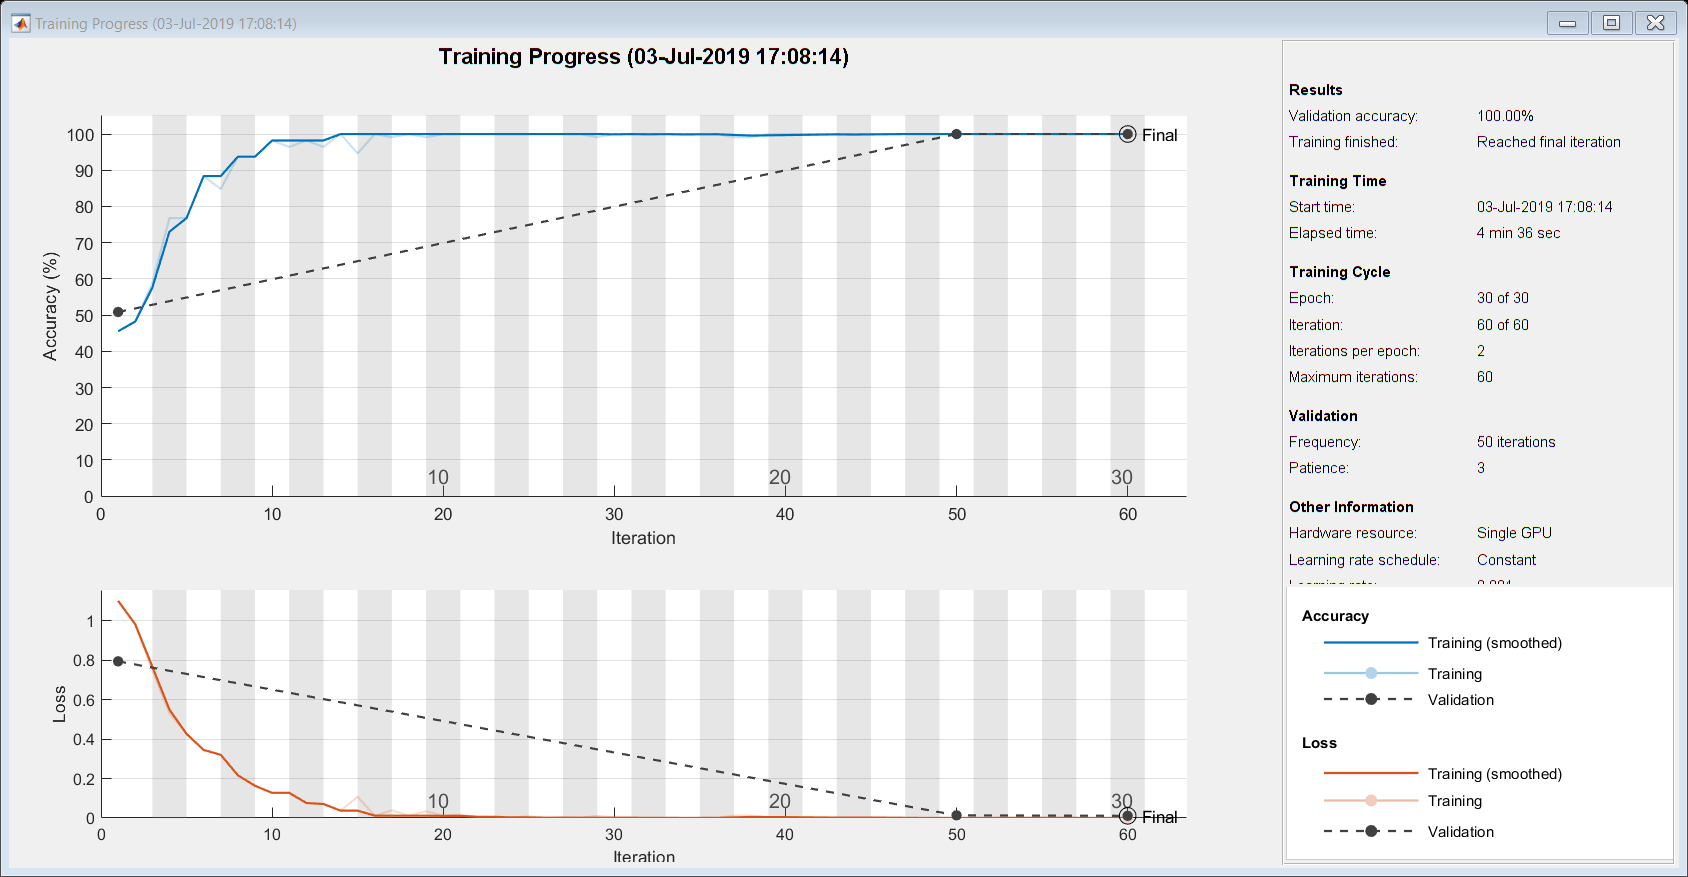

Training on single GPU.


Initializing image normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:08 |       45.54% |       50.85% |       1.1003 |       0.7937 |          0.0010 |
|      25 |          50 |       00:03:54 |      100.00% |      100.00% |       0.0006 |       0.0136 |          0.0010 |
|      30 |          60 |       00:04:36 |      100.00% |      100.00% |       0.0005 |       0.0111 |          0.0010 |
|======================================================================================================================

%Training the model
doTraining = true;

if doTraining
    disp('Initialization may take a minute before training begins');
    net_Face = trainNetwork(trainDS, newLayers, trainOpts);
end

%save AlexNetTransferLearning net_Face

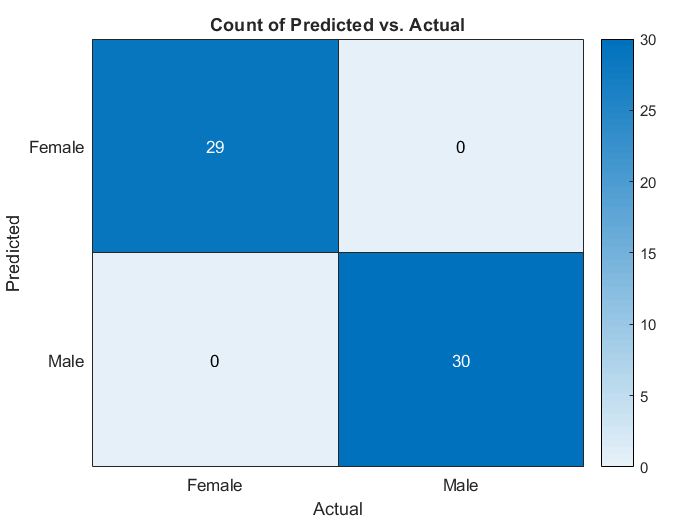

%Testing
doTest = true;

if doTest
    [labels, scores] = classify(net_Face, testDS);
else
    load testResults.mat 
end

% Calculate accuracy
accuracy = sum(labels == testDS.Labels)/numel(labels);

% Confusion Matrix - visual inspection of accuracy and error
tbl = table(labels,testDS.Labels,...
    'VariableNames', {'Predicted', 'Actual'});

figure('name','Confusion Matrix')
heatmap(tbl,'Actual','Predicted');


% Are there trends in the misclassifications?
% Where might these come from?

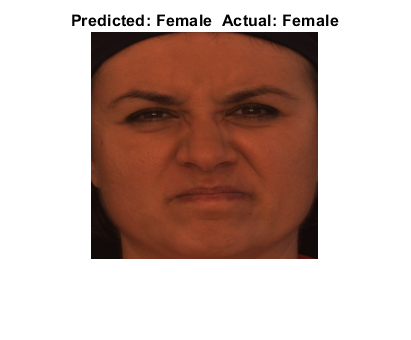


randNum = randi(length(testDS.Files));
imOriginal = readimage(testDS,randNum);
imResized = imresize(imOriginal, inputSize);

actualLabel = testDS.Labels(randNum);
predictedLabel = classify(net_Face,imResized);
imshow(imOriginal)
title(['Predicted: ' char(predictedLabel) '  Actual: ' char(actualLabel)],'Interpreter','none')

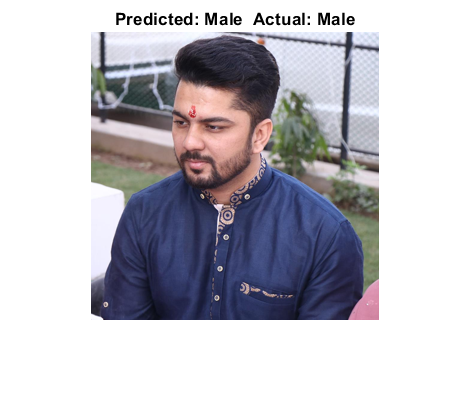

a='sahil.jpg';
imOriginal = imread(a);
imResized = imresize(imOriginal, inputSize);
actualLabel = 'Male';
predictedLabel = classify(net_Face,imResized);
imshow(imresize(imOriginal,0.3))
title(['Predicted: ' char(predictedLabel) '  Actual: ' char(actualLabel)],'Interpreter','none')